% `dbstack` returns the call stack. For a live script, this is always at
% least three items long (in my testing). Here, we detect if it's longer
% than that, which means that we're being called by another script
is_main = length(dbstack) <= 3

is_main = logical
   1



% We allow the global variable of load_smiles to be set to "pass in"
% if we should train with only non-smiling images but test with only
% similing images.
global load_smiles_only
if ~exist("num_eigenvectors", "var") || isempty(load_smiles_only) || (load_smiles_only ~= 1 && load_smiles_only ~= 0)
    load_smiles_only = true;
end

if load_smiles_only
    load("classdata_smile.mat");
    load("classdata_no_smile.mat");
else
    load("classdata_train.mat");
    load("classdata_test.mat");
end

% We allow the global variable of num_eigenvectors to be set to "pass in" a
% precision level.
global num_eigenvectors
if ~exist("num_eigenvectors", "var") || isempty(num_eigenvectors) || num_eigenvectors < 1
    num_eigenvectors = 10;
end

disp("Using Eigenvectors: " + num_eigenvectors);

Using Eigenvectors: 7



train_sample_idx = 42; % index of a sample image to use for validation of the training process
test_sample_idx = 42; % index of a sample image to use for validation of the testing process

## Training

% First, we convert all the images to row vectors
train_faces = imgs_to_row(grayfaces_train);

% Then make sure we haven't corrupted the images yet
figure; disp("Training Sample Face, Reshaped, Unmodified:");

Training Sample Face, Reshaped, Unmodified:


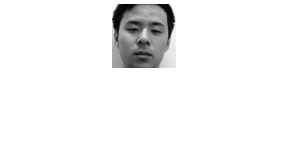

imshow(imgs_to_grid(train_faces(train_sample_idx, :)), []);

% Now, we need to mean-center all the faces. We'll store the mean so we can
% easily un-do this later to display processed images.
train_face_mean = mean(train_faces);
train_faces_centered = train_faces - train_face_mean;

% Double-check that we can still successfully read and display one of the
% images.
disp("Training Sample Face, Mean-Adjusted, Uncompressed:");

Training Sample Face, Mean-Adjusted, Uncompressed:


imshow(imgs_to_grid(train_faces_centered(train_sample_idx, :), train_face_mean), []);

% Now, we can actually do the Principal Component Analysis!
train_faces_covariance = train_faces_centered' * train_faces_centered;
[eigenvectors, ~] = eigs(train_faces_covariance, num_eigenvectors); % ignoring second result, which is eigenvalues

% Now, let's project all the training data onto our eigenvectors, therefore
% compressing it
train_faces_compressed = train_faces_centered * eigenvectors;

% For validation purposes, let's decompress the image (project it back to
% the standard basis), and draw it
decompressed_train_faces = train_faces_compressed * eigenvectors';

disp("Training Sample Face, Decompressed:");

Training Sample Face, Decompressed:


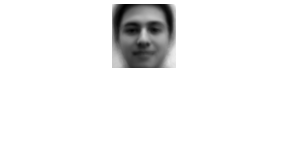

imshow(imgs_to_grid(decompressed_train_faces(train_sample_idx, :), train_face_mean), []);

## Testing

% Let's load the data
load("classdata_test.mat");
test_faces = imgs_to_row(grayfaces_test);

% Then make sure we haven't corrupted the images yet
disp("Testing Sample Face, Reshaped, Unmodified:");

Testing Sample Face, Reshaped, Unmodified:


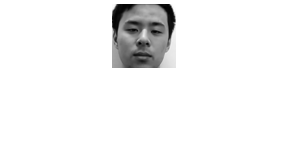

imshow(imgs_to_grid(test_faces(test_sample_idx, :)), []);

% Now, we need to mean-center all the faces.
% NB: We're centering it on the mean of the testing faces, not the training
% faces, meaning that the testing and training images are being centered
% around a different point, which is questionable.
test_face_mean = mean(test_faces);
test_faces_centered = test_faces - train_face_mean;

% Double-check that we can still successfully read and display one of the
% images.
disp("Training Sample Face, Mean-Adjusted, Uncompressed:");

Training Sample Face, Mean-Adjusted, Uncompressed:


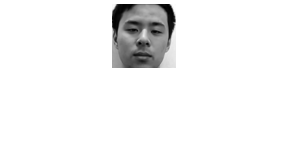

imshow(imgs_to_grid(test_faces_centered(test_sample_idx, :), test_face_mean), []);

% Now, we can actually do the Principal Component Analysis!
%test_faces_covariance = test_faces_centered' * test_faces_centered;
%[eigenvectors, ~] = eigs(test_faces_covariance, num_eigenvectors); % ignoring second result, which is eigenvalues

% Now, let's project all the testing data onto our eigenvectors, therefore
% compressing it
test_faces_compressed = test_faces_centered * eigenvectors;

% For validation purposes, let's decompress an image (project it back to
% the standard basis), and draw it.
decompressed_test_faces = test_faces_compressed * eigenvectors';

disp("Training Sample Face, Decompressed:");

Training Sample Face, Decompressed:


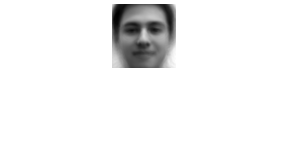

imshow(imgs_to_grid(decompressed_test_faces(test_sample_idx, :), test_face_mean), []);

% Now, that we've projected both the training faces and the testing faces
% onto our eigenvectors, let's figure out the nearest neighbor in the
% training dataset of each of the testing faces. We'll assume that the
% nearest neighbor is the same person.
nearest_neighbors = knnsearch(train_faces_compressed, test_faces_compressed);

% Finally, we can compare the results of our algorithm with the correct
% answers in subject_tests
% Mean here is a shortcut, since the mean of 0 for wrong or 1 for right
% will be percent correct.
percent_correct = mean(subject_train(nearest_neighbors) == subject_test)

percent_correct = 0.9607

## Helper Functions

function out = imgs_to_grid(imgs, mean)
    %%
    % Convert a 2D matrix of images as row vectors (img, pikel) to a 3D array of images as
    % grids (x, y, img). If mean is provided, also add it to each pixel.
    %%
    if nargin < 2
        mean = 0;
    end
    
    out = reshape(imgs + mean, [sqrt(size(imgs, 2)), sqrt(size(imgs, 2)), size(imgs, 1)]);
end

function out = imgs_to_row(imgs)
    %%
    % Convert a 3D array of images (x, y, img) to a 2D matrix of images as
    % row vectors (img, pixel).
    %%
    out = reshape(imgs, [size(imgs, 1) * size(imgs, 2) size(imgs, 3)])';
end

function debuglog(text)
    if ~is_main
        return
    end
    disp(text);
end

function imshow_row(img, mean)
    if ~is_main
        return
    end
    imshow_row(imgs_to_grid(img, mean), [])
end